%Here we are generating the four regions signal, that we use in figure 3 of
%the paper

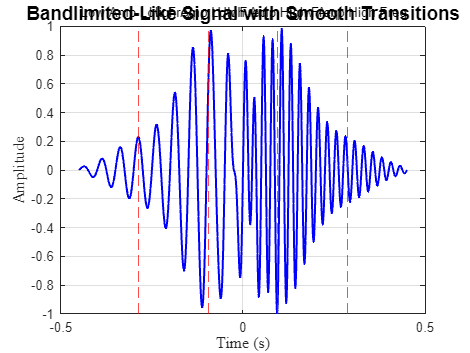


% Parameters
dt = 0.000001; % time step for integral as well
Td = 0.000001; % how far I'm placing the sincs

Tmax=0.45;
td = (-Tmax:Td:Tmax).'; % Display sampling
% Define time boundaries
T_total = td(end) - td(1);      % Total duration (0.9 s)
T_seg = T_total / 4;            % Each segment duration (~0.225 s)

% Segment centers
centers = linspace(-0.2875, 0.2875, 4);  % Center of each segment

% Frequencies (Hz)
f_low = 20;
f_high = 40;

% Amplitudes
A_low = 0.2;
A_high = 1.0;

% Gaussian envelope width (controls smoothness)
sigma = T_seg / 3;

% Initialize signal
fd = zeros(size(td));

% Segment 1: Low Amp, Low Freq
fd = fd + A_low  * sin(2*pi*f_low*td)  .* exp(-((td - centers(1)).^2)/(2*sigma^2));

% Segment 2: High Amp, Low Freq
fd = fd + A_high * sin(2*pi*f_low*td)  .* exp(-((td - centers(2)).^2)/(2*sigma^2));

% Segment 3: High Amp, High Freq
fd = fd + A_high * sin(2*pi*f_high*td) .* exp(-((td - centers(3)).^2)/(2*sigma^2));

% Segment 4: Low Amp, High Freq
fd = fd + A_low  * sin(2*pi*f_high*td) .* exp(-((td - centers(4)).^2)/(2*sigma^2));

% Optional: Normalize for visualization
fd = fd / max(abs(fd));
save('four_regions.mat', 'fd', 'td');
% Plot
figure;
plot(td, fd, 'b', 'LineWidth', 1.5);
xlabel('Time (s)', 'FontSize', 12, 'FontName', 'Times');
ylabel('Amplitude', 'FontSize', 12, 'FontName', 'Times');
title('Bandlimited-Like Signal with Smooth Transitions', 'FontSize', 14);
grid on;

% Vertical lines to show approximate segment boundaries
xline(centers(1), '--r');
xline(centers(2), '--r');
xline(centers(3), '--r');
xline(centers(4), '--r');

% Annotations
text(centers(1), 1.1, 'Low Amp Low Freq',  'HorizontalAlignment', 'center');
text(centers(2), 1.1, 'High Amp Low Freq', 'HorizontalAlignment', 'center');
text(centers(3), 1.1, 'High Amp High Freq','HorizontalAlignment', 'center');
text(centers(4), 1.1, 'Low Amp High Freq', 'HorizontalAlignment', 'center');